dat = readmatrix("sample_data_1.txt") ;
retention_time = dat(:,1) ;
intensity = dat(:,2) ;

tic ;
[baseline,noise] = sgolay_robust(intensity,retention_time,2000,3,1) ;
toc

Elapsed time is 62.036512 seconds.


tic ;
[baseline_interp,noise_interp] = sgolay_robust(intensity,retention_time,2000,3,100) ;
toc

Elapsed time is 0.621628 seconds.


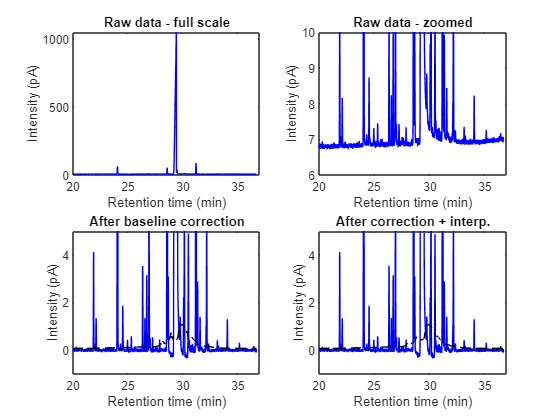

figure ;

subplot(2,2,1) ;
plot(retention_time,intensity,'b-') ;
xlabel("Retention time (min)") ;
ylabel("Intensity (pA)") ;
xlim([20 37]) ;
title("Raw data - full scale") ;

subplot(2,2,2) ;
plot(retention_time,intensity,'b-') ;
xlabel("Retention time (min)") ;
ylabel("Intensity (pA)") ;
ylim([6 10]) ; xlim([20 37]) ;
title("Raw data - zoomed") ;

subplot(2,2,3) ;
plot(retention_time,intensity-baseline,'b-',retention_time,3*noise,'k--') ;
xlabel("Retention time (min)") ;
ylabel("Intensity (pA)") ;
ylim([-1 5]) ; xlim([20 37]) ;
title("After baseline correction") ;

subplot(2,2,4) ;
plot(retention_time,intensity-baseline_interp,'b-',retention_time,3*noise_interp,'k--') ;
xlabel("Retention time (min)") ;
ylabel("Intensity (pA)") ;
ylim([-1 5]) ; xlim([20 37]) ;
title("After correction + interp.") ;